% AAE 666 HW7 Exercise 4
% Tomoki Koike
close all; clear all; clc;

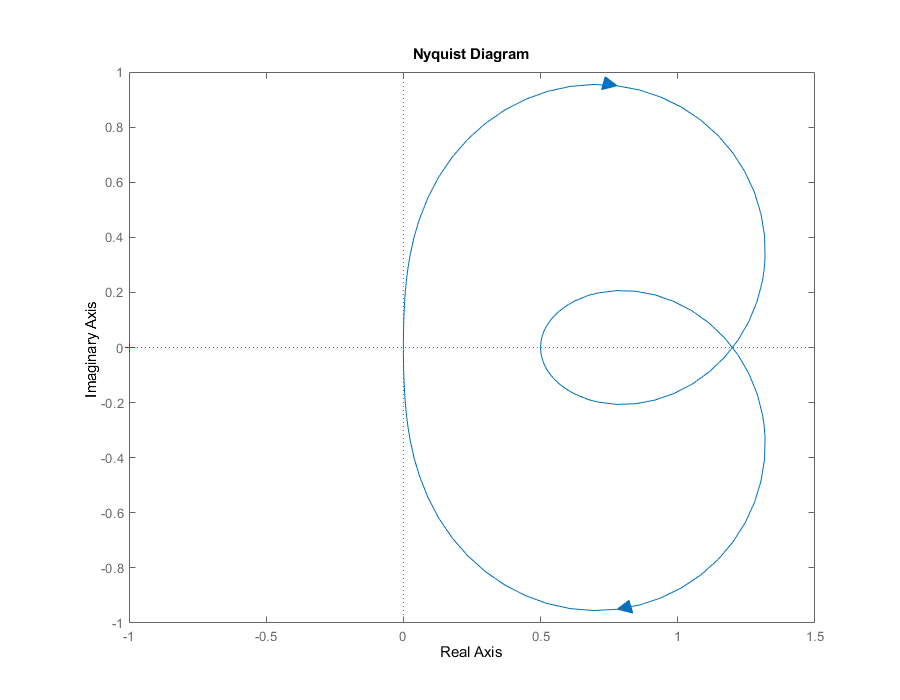

% Control matrices 
beta = 1.2;
A = [0 1; -2 -1];
B = [0; 1];
C = [1, beta];
D = 0;

% Nyquist Plot 
sys = ss(A,B,C,D);
fig = figure("Renderer","painters","Position",[60 60 900 700]); 
nyquist(sys);  
saveas(fig, "ex4_nyquist.png")


% Observability and Controllability 
Qc = ctrb(A,B);
rankQc = rref(Qc);
Qo = obsv(A,C);
rankQo = rref(Qo);

echo off;
% Quadratic stability LMI of the problem 

% Setup LMI
setlmis([]);
% P matrix
p = lmivar(1, [2, 1]);  % P
a = lmivar(1, [1, 1]);  % alpha

if D == 0
    % Equation 1
    lmi1 = newlmi;
    lmiterm([-lmi1, 1, 1, 0], a);  % aI
    lmiterm([-lmi1, 1, 2, 1], B', p);  % B'P
    lmiterm([-lmi1, 1, 2, 0], -C);  % -C
    lmiterm([-lmi1, 2, 2, 0], a);  % aI
    
    % Equation 2
    lmi2 = newlmi;
    lmiterm([lmi2, 1, 1, p], 1, A, 's');  % PA + A'P
    
    % Equation 3
    lmi3 = newlmi;
    lmiterm([-lmi3, 1, 1, p], 1, 1);  % 0 < P
    
    lmi4 = newlmi;
    lmiterm([lmi4, 1, 1, a], 1, 1);
else
    % Equation 1
    lmi1 = newlmi;
    lmiterm([lmi1, 1, 1, p], 1, A, 's');  % PA + A'P
    lmiterm([lmi1, 1, 1, a], 2, p);       % 2aP
    lmiterm([lmi1, 1, 2, p], 1, B);       % PB
    lmiterm([lmi1, 1, 2, 0], -C');        % -C'
    
    lmiterm([lmi1, 2, 2, 0],-D);          % -D
    lmiterm([lmi1, 2, 2, 0],-D');         % -D'
    
    % Equation 2
    lmi2 = newlmi;
    lmiterm([-lmi2, 1, 1, p], 1, 1);  % 0 < P
    
    % Equation 3
    lmi3 = newlmi;
    lmiterm([-lmi3, 1, 1, a], 1, 1);  % 0 < a
end

% Configure for solver
lmis = getlmis;


% Results
[tfeas, xfeas] = feasp(lmis);


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -1.354762

 Result:  best value of t:    -1.354762
          f-radius saturation:  0.000% of R =  1.00e+09
 


P = dec2mat(lmis, xfeas, p);
v1 = defcx(lmis, 2, a);
c = mat2dec(lmis, v1);
options = [1e-5 0 0 0 0];
[alpha, xopt] = mincx(lmis, c, options);


 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1               0.000000e+00
     2               0.000000e+00
     3               0.000000e+00
     4               0.000000e+00
     5               0.000000e+00
     6               0.000000e+00
     7               0.000000e+00
     8               0.000000e+00
     9               0.000000e+00
    10               0.000000e+00
    11               0.000000e+00
    12               0.000000e+00
    13               0.000000e+00
    14               0.000000e+00
    15               0.000000e+00
    16               0.000000e+00
    17               0.000000e+00
    18               0.000000e+00
    19               0.000000e+00
    20               0.000000e+00
    21               0.000000e+00
    22               0.000000e+00
    23               0.000000e+00
    24               0.000000e+00
    25               0.000000e+00
    26               0.000000e+00

    
assert(tfeas < 0, "This results is infeasible.");

% Save file as .m
matlab.internal.liveeditor.openAndConvert('aae666_hw7_ex4.mlx', ...
    convertStringsToChars('aae666_hw7_ex4.m'));

sym(P)

$$ans = \left(\begin{array}{cc} 3.3731 & 0.5415\\ 0.5415 & 1.5927 \end{array}\right)$$

sym(eig(P))

$$ans = \left(\begin{array}{c} 1.4409\\ 3.5249 \end{array}\right)$$